# Create and Customize 3-D Bubble Charts

Bubble charts display colored circular markers (bubbles) with varying sizes.

## Read Cars Data

We will use "`carsmall.mat" `to demonstrate how to create and customize 3-D bubblecharts. The MAT-file contains various measurement data of 100 models of cars such as MPG, Horsepower, Displacement, etc. released in different countries between 1970 and 1982. 

load("carsmall.mat")

## Basic 3-D Bubble Chart

View the distribution of vehicles based on fuel economy (MPG), Weight and Displacement with bubbles sized by vehicle horsepower. From the chart, there's a clear trend that heavier, higher displacement vehicles that are less fuel efficient have a higher horsepower output.

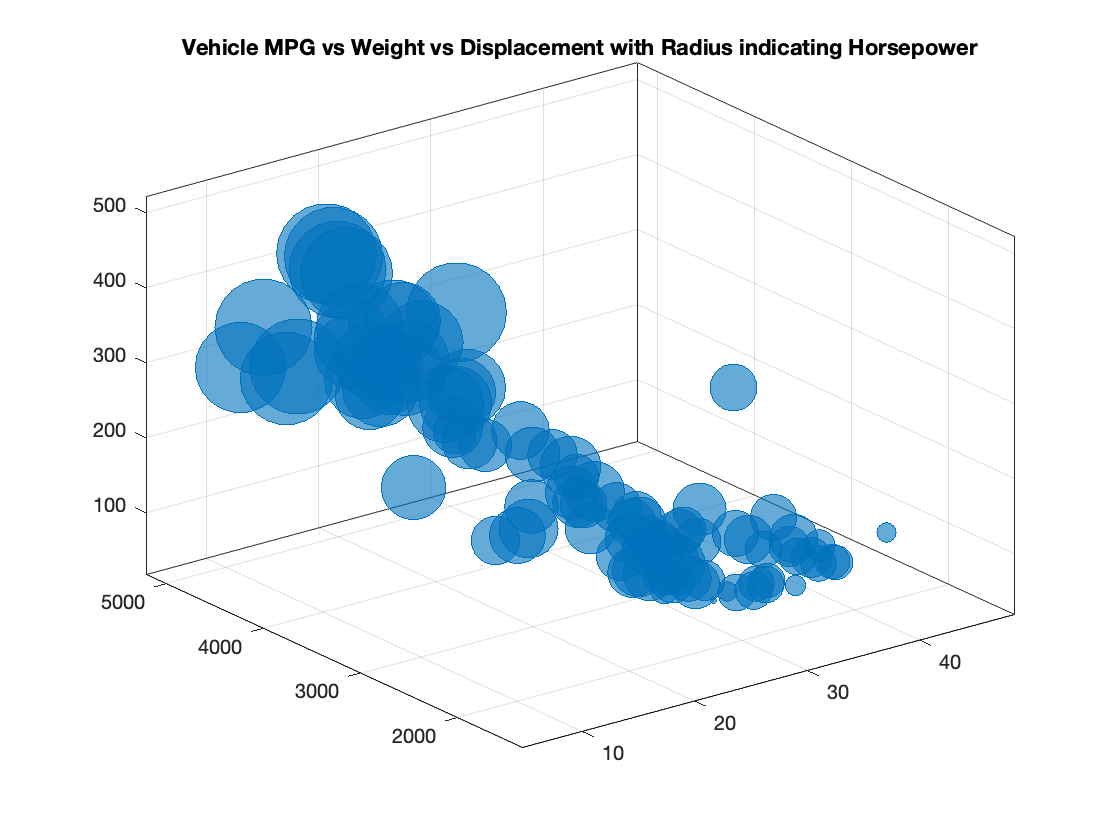

bubblechart3(MPG,Weight,Displacement,Horsepower);
title("Vehicle MPG vs Weight vs Displacement with Radius indicating Horsepower")

## Customization

### Change Bubble Transparency

To better visualize bubbles where they are very clustered on the top left, increase the transparency of the bubbles by specifying the *MarkerFaceAlpha* property as a Name, Value pair argument to `bubblechart3`.

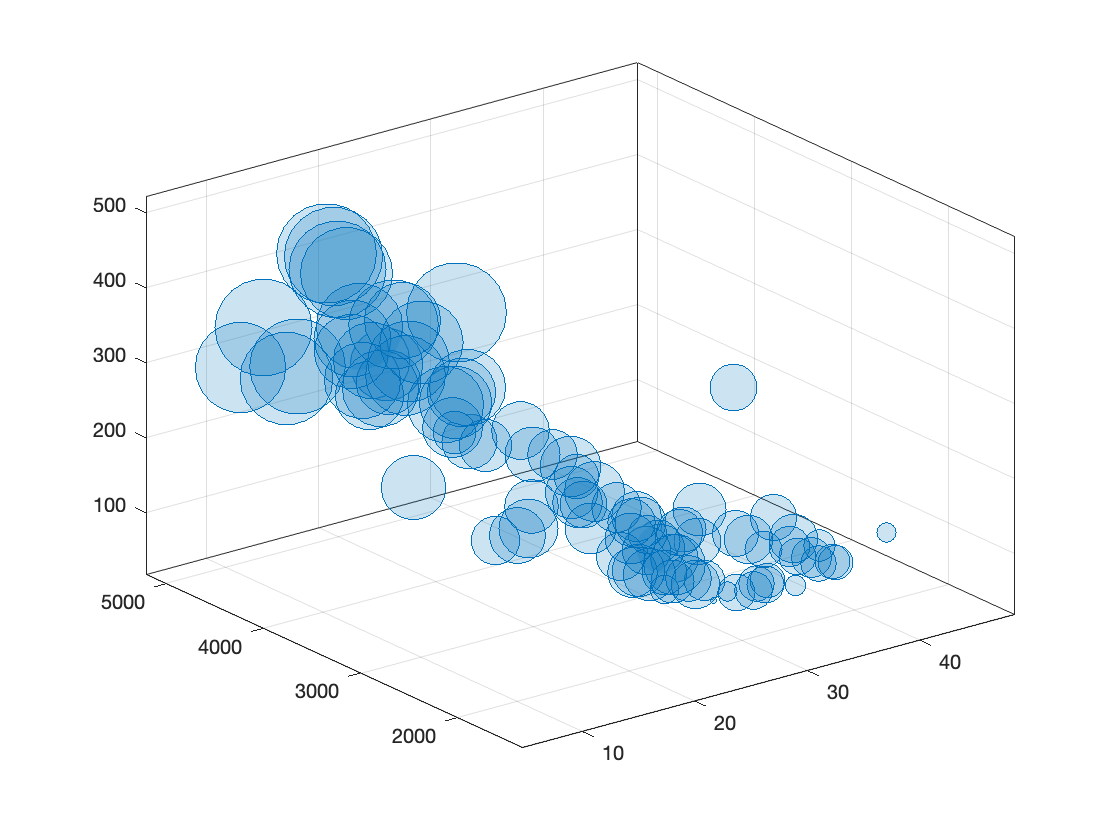

markerFaceAlpha = 0.2;
b = bubblechart3(MPG,Weight,Displacement,Horsepower,...
    "MarkerFaceAlpha",markerFaceAlpha); % Specify bubble transparency

### Add a Bubble Legend and Axes Labels

The Bubble Legend can be used to indicate what horsepower values the relative sizes of the bubble represent. Place the bubble legend outside the chart by specifying the bubblelegend *Location* attribute.

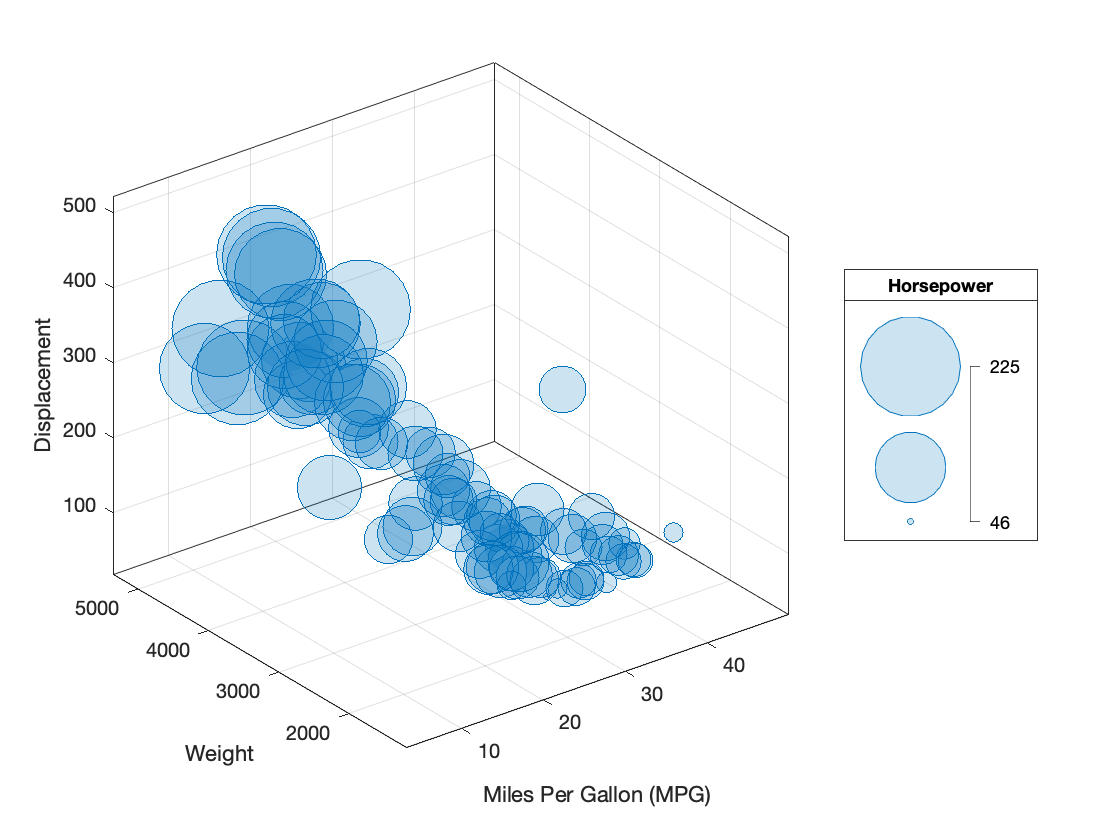

legendLocation = "eastoutside";
figure
b1 = bubblechart3(MPG,Weight,Displacement,Horsepower,...
    "MarkerFaceAlpha",0.2);

xlabel("Miles Per Gallon (MPG)");
ylabel("Weight");
zlabel("Displacement");
blgd = bubblelegend("Horsepower");
blgd.Location = legendLocation;    % Specify legend location

### Specify Different Bubble Colors

If the model year of each vehicle needs to be distinguished, use the 5th input argument to `bubblechart3`, *c*, to distinguish the colors of the bubbles based on the vehicle model year. It becomes clear from the chart that later model years produced lighter and more fuel efficient vehicles.

b2 = bubblechart3(MPG,Weight,Displacement,Horsepower,...
    Model_Year,...  % Specify variable used to distinguish bubble colors
    "MarkerFaceAlpha",0.2);
xlabel("Miles Per Gallon (MPG)");
ylabel("Weight")
zlabel("Displacement")
bubblelegend("Horsepower","Location","eastoutside");
title("Vehicle MPG vs Weight vs Displacement with Radius indicating Horsepower")

### Include and Customize a Color Bar

Use `colorbar` to highlight the different model years and reduce the colormap to 3 colors representing the 3 Model Years from the data set. Use the *Ticks *and *TickLabels* Name, Value pairs to customize the colorbar. Add a label to the colorbar using `ylabel`.

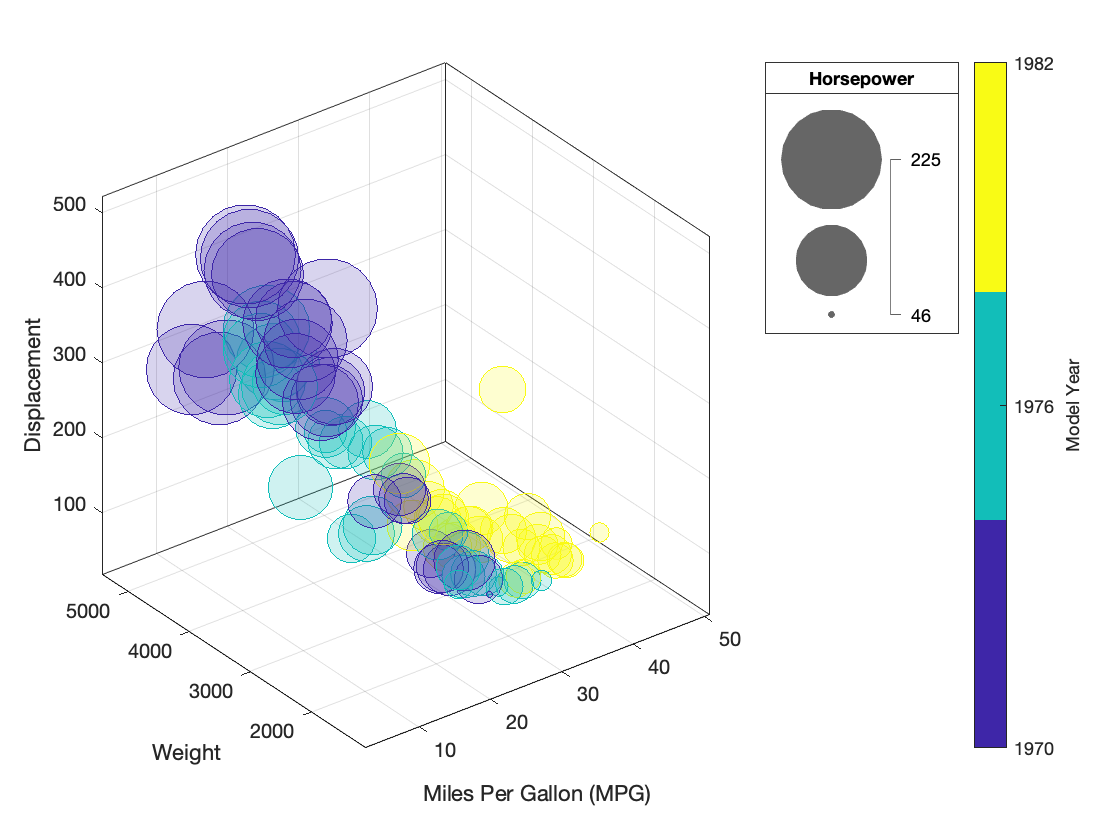

colormap(parula(3))
c = colorbar("Ticks",unique(Model_Year),...
    "TickLabels",["1970","1976","1982"]);
ylabel(c,"Model Year");

## **Additional Information**

### **Get All BubbleChart Properties**

Graphics objects in MATLAB have many properties. To see all the properties of a BubbleChart, uncomment the following code. View or modify these properties using dot notation.

% get(b)

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[bubblechart3](https://www.mathworks.com/help/matlab/ref/bubblechart3.html)

Copyright (c) 2021, The MathWorks, Inc.